% =========================================================================
% MATLAB SCRIPT FOR DIRECTIONAL COUPLER ANALYSIS
% =========================================================================
% Project: IE766 - Projeto 2
% Author: Pedro Felipe Lucena Lima
%
% --- VERSION 6 (CMT VS. SUPERMODE COMPARISON) ---
%
% Description:
% This script performs a comprehensive analysis of a directional coupler.
% 1. Compares the analytical Coupled Mode Theory (CMT) results for Lc vs.
%    Gap against a provided vector of Supermode simulation results.
% 2. Calculates and plots the normalized power transfer for a specific
%    design point (fixed gap and wavelength).
%
% =========================================================================

%% Clear Workspace
clear;
close all;
clc;

%% SECTION 1: PHYSICAL AND WAVEGUIDE PARAMETERS
% -------------------------------------------------------------------------
% Define the constants and parameters for the simulation.

% Refractive Indices
n_core = 3.48;          % Core refractive index (Silicon)
n_cladding = 1.45;      % Cladding refractive index (Silica)

% Geometric Parameters (in meters)
W = 500e-9;             % Waveguide width (500 nm)
H = 220e-9;             % Waveguide height (220 nm)
a = W / 2;              % Half-width of the waveguide

% --- Analysis Parameters ---
lambda0_um = 1.58;      % Your specific wavelength for comparison
lambda0_m = lambda0_um * 1e-6;

%% SECTION 2: SUPERMODE DATA
% -------------------------------------------------------------------------
% Data obtained from Lumerical MODE simulations (or provided).

gap_supermode_nm = [10, 20, 30, 40, 50, 60, 70, 80, 90, 100];
Lc_supermode_um  = [3.3072, 4.2875, 5.2751, 6.2820, 7.3179, 8.3922, 9.5138, 10.6922, 11.9371, 13.2581];
fprintf('--- Supermode Data Loaded ---\n');

--- Supermode Data Loaded ---


fprintf('This data will be plotted against the CMT calculations.\n\n');

This data will be plotted against the CMT calculations.



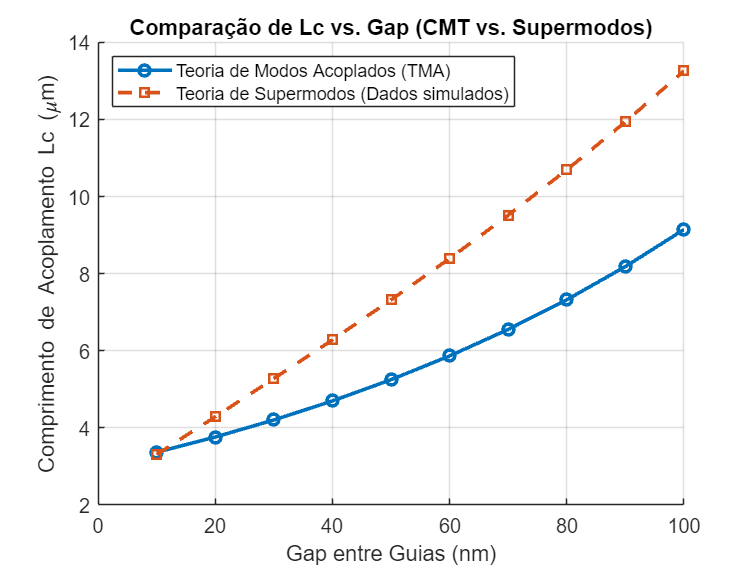


%% SECTION 3: CMT CALCULATION AND COMPARATIVE PLOT
% -------------------------------------------------------------------------
% Calculate Lc using CMT for the same gap values as the supermode data.

gap_values_m = gap_supermode_nm * 1e-9; % Use the same gap vector
Lc_cmt_um = zeros(size(gap_values_m));  % Pre-allocate results array

for i = 1:length(gap_values_m)
    gap = gap_values_m(i);
    
    % --- Core Calculations (for each gap at the design wavelength) ---
    k0 = 2 * pi / lambda0_m;
    delta = (n_core^2 - n_cladding^2) / (2 * n_core^2);
    V = k0 * a * sqrt(n_core^2 - n_cladding^2);
    
    % Use TM-like eigenvalue equation
    eigen_func = @(u) u .* tan(u) - (n_core/n_cladding)^2 .* sqrt(V^2 - u.^2);
    try
        u_solution = fzero(eigen_func, [0, pi/2-1e-6]);
    catch
        Lc_cmt_um(i) = NaN; continue;
    end
    
    kx_a = u_solution;
    gamma_x_a = sqrt(V^2 - kx_a^2);
    gamma_x = gamma_x_a / a;
    
    % Use the empirically-adjusted Okamoto formula for K
    C1 = (sqrt(2*delta) * (kx_a)^2 * (gamma_x_a)^2) / (a * (1 + gamma_x_a) * V^3);
    K = C1 * exp(-gamma_x * gap);
    
    % Calculate Lc and store it in the results array (in um)
    Lc = pi / (2 * K);
    Lc_cmt_um(i) = Lc * 1e6;
end

% --- Generate the Comparative Plot ---
figure; hold on;

% Plot CMT results
plot(gap_supermode_nm, Lc_cmt_um, '-o', 'LineWidth', 2, 'DisplayName', 'Teoria de Modos Acoplados (TMA)');

% Plot Supermode results
plot(gap_supermode_nm, Lc_supermode_um, '--s', 'LineWidth', 2, 'DisplayName', 'Teoria de Supermodos (Dados simulados)');

hold off;
title('Comparação de Lc vs. Gap (CMT vs. Supermodos)', 'FontSize', 14);
xlabel('Gap entre Guias (nm)', 'FontSize', 12);
ylabel('Comprimento de Acoplamento Lc (\mum)', 'FontSize', 12);
grid on; set(gca, 'FontSize', 11);
legend('Location', 'northwest');

fprintf('CMT vs. Supermode plot generated successfully.\n');

CMT vs. Supermode plot generated successfully.



%% SECTION 4: NORMALIZED POWER VS. LENGTH PLOT
% -------------------------------------------------------------------------
% This section calculates and plots power exchange for a specific design.

fprintf('\n--- Generating Normalized Power Plot ---\n');


--- Generating Normalized Power Plot ---



% --- Define a specific design point to analyze ---
gap_design_nm = 70; % Let's pick a gap where Lc is close to 10 um
idx_design = find(gap_supermode_nm == gap_design_nm);
Lc_design_um = Lc_supermode_um(idx_design); % Use the more accurate Lc
Lc_design_m = Lc_design_um * 1e-6;

fprintf('Analyzing for lambda = %.2f um and gap = %.0f nm.\n', lambda0_um, gap_design_nm);

Analyzing for lambda = 1.58 um and gap = 70 nm.


fprintf('Using the Supermode Lc for this design: %.2f um\n', Lc_design_um);

Using the Supermode Lc for this design: 9.51 um


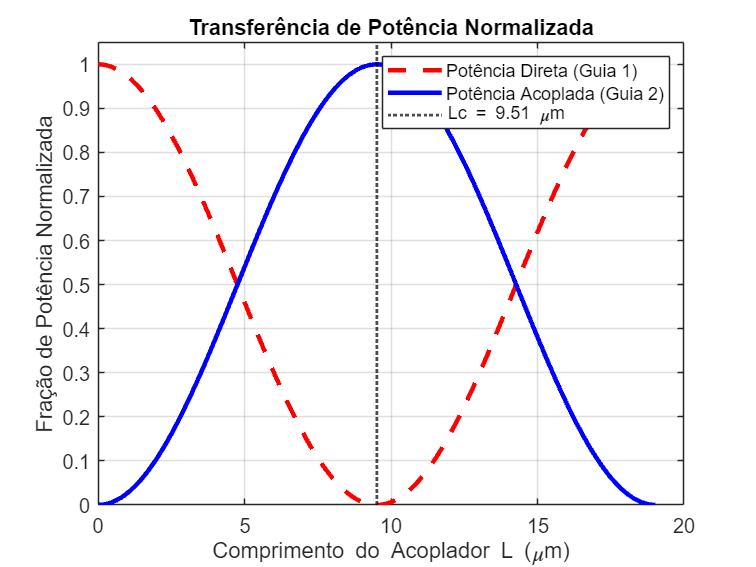


% --- Calculate Power Curves ---
L_vector = linspace(0, 2 * Lc_design_m, 500); % Length vector from 0 to 2*Lc
C = pi / (2 * Lc_design_m); % Coupling coefficient from Lc

P_through = cos(C * L_vector).^2; % Power in through port
P_coupled = sin(C * L_vector).^2; % Power in coupled port

% --- Plot the Power Curves ---
figure;
plot(L_vector*1e6, P_through, 'r--', 'LineWidth', 2.5, 'DisplayName', 'Potência Direta (Guia 1)');
hold on;
plot(L_vector*1e6, P_coupled, 'b-', 'LineWidth', 2.5, 'DisplayName', 'Potência Acoplada (Guia 2)');
xline(Lc_design_um, 'k:', 'LineWidth', 1.5, 'DisplayName', sprintf('Lc = %.2f \\mum', Lc_design_um));
hold off;

% --- Formatting ---
title('Transferência de Potência Normalizada', 'FontSize', 14);
xlabel('Comprimento do Acoplador L (\mum)', 'FontSize', 12);
ylabel('Fração de Potência Normalizada', 'FontSize', 12);
grid on;
ylim([0, 1.05]); % Set y-axis limits
legend('Location', 'northeast');
set(gca, 'FontSize', 11);


fprintf('Normalized Power plot generated successfully.\n');

Normalized Power plot generated successfully.
